# Contest Report

% Read in the list of all solvers
solvers = readtimetable("allSolvers.csv");

% Get rid of bad entries
% The result may be infinite or negative. Neither is a good state.
ix = isinf(solvers.result)|(solvers.result<0);
solvers(ix,:) = [];

Here is the list of all the solvers

solvers

solvers = 2x5 timetable
             t              result    computeTime    score        author                          commit                   
    ____________________    ______    ___________    ______    ____________    ____________________________________________

    07-Aug-2024 17:40:34    103.18      0.28249      544.13    {'MAXPIL0T'}    {'e40e8a6b1ac3ec055b2fd92398bd616a01a589de'}
    07-Aug-2024 18:35:16    103.18      0.23021       538.9    {'MAXPIL0T'}    {'210f97a3c6ade05db23fa4d2ebb8ee12c0c0ad89'}


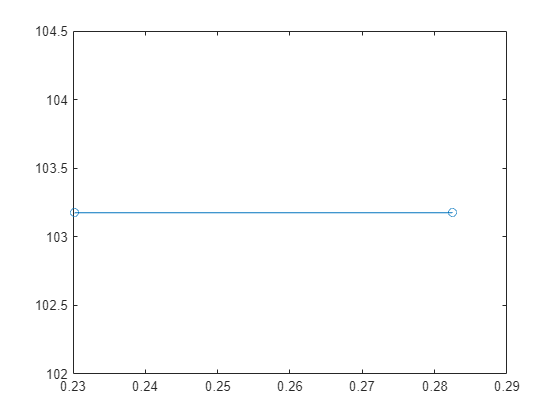

plot(solvers.computeTime,solvers.result,"-o")

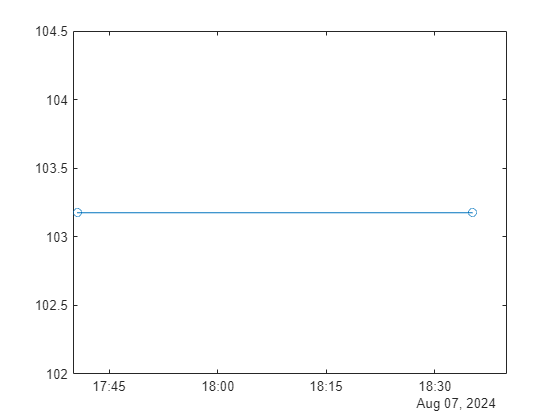

plot(solvers.t,solvers.result,"-o")

Calculate leaders

bestScore = inf;
ixLeader = zeros(height(t),1);

Unrecognized function or variable 't'.

for i = 1:height(solvers)
    if solvers.score(i) < bestScore
        ixLeader(i) = 1;
        bestScore = solvers.score(i);
    end
end

leaders = solvers(ixLeader,:)

